# Setting up a PWM-based power electronics model for fast simulation

Copyright 2023-2024 The MathWorks, Inc.

## Goal of the simulation

If you want to optimize a PWM-based power electroncis model like motor control it is important to determine first what the goal of the simulation is.

Typically PWM is simulated for 

- Harmonics Analysis or

- Exploration of Power Losses (including the switching Power Losses in the Inverter)

### Exploration of Power Losses

Here the MOSFET (or IGBT) Inverter + Diode with charging dynamics should be used.

### Harmonics Analysis

Here the Ideal Switching Inverter + Diode should be used or 

the average inverter model together with subcycle averaging. 

### Control Design

Here the averaged model is the appropriate fidelity level.

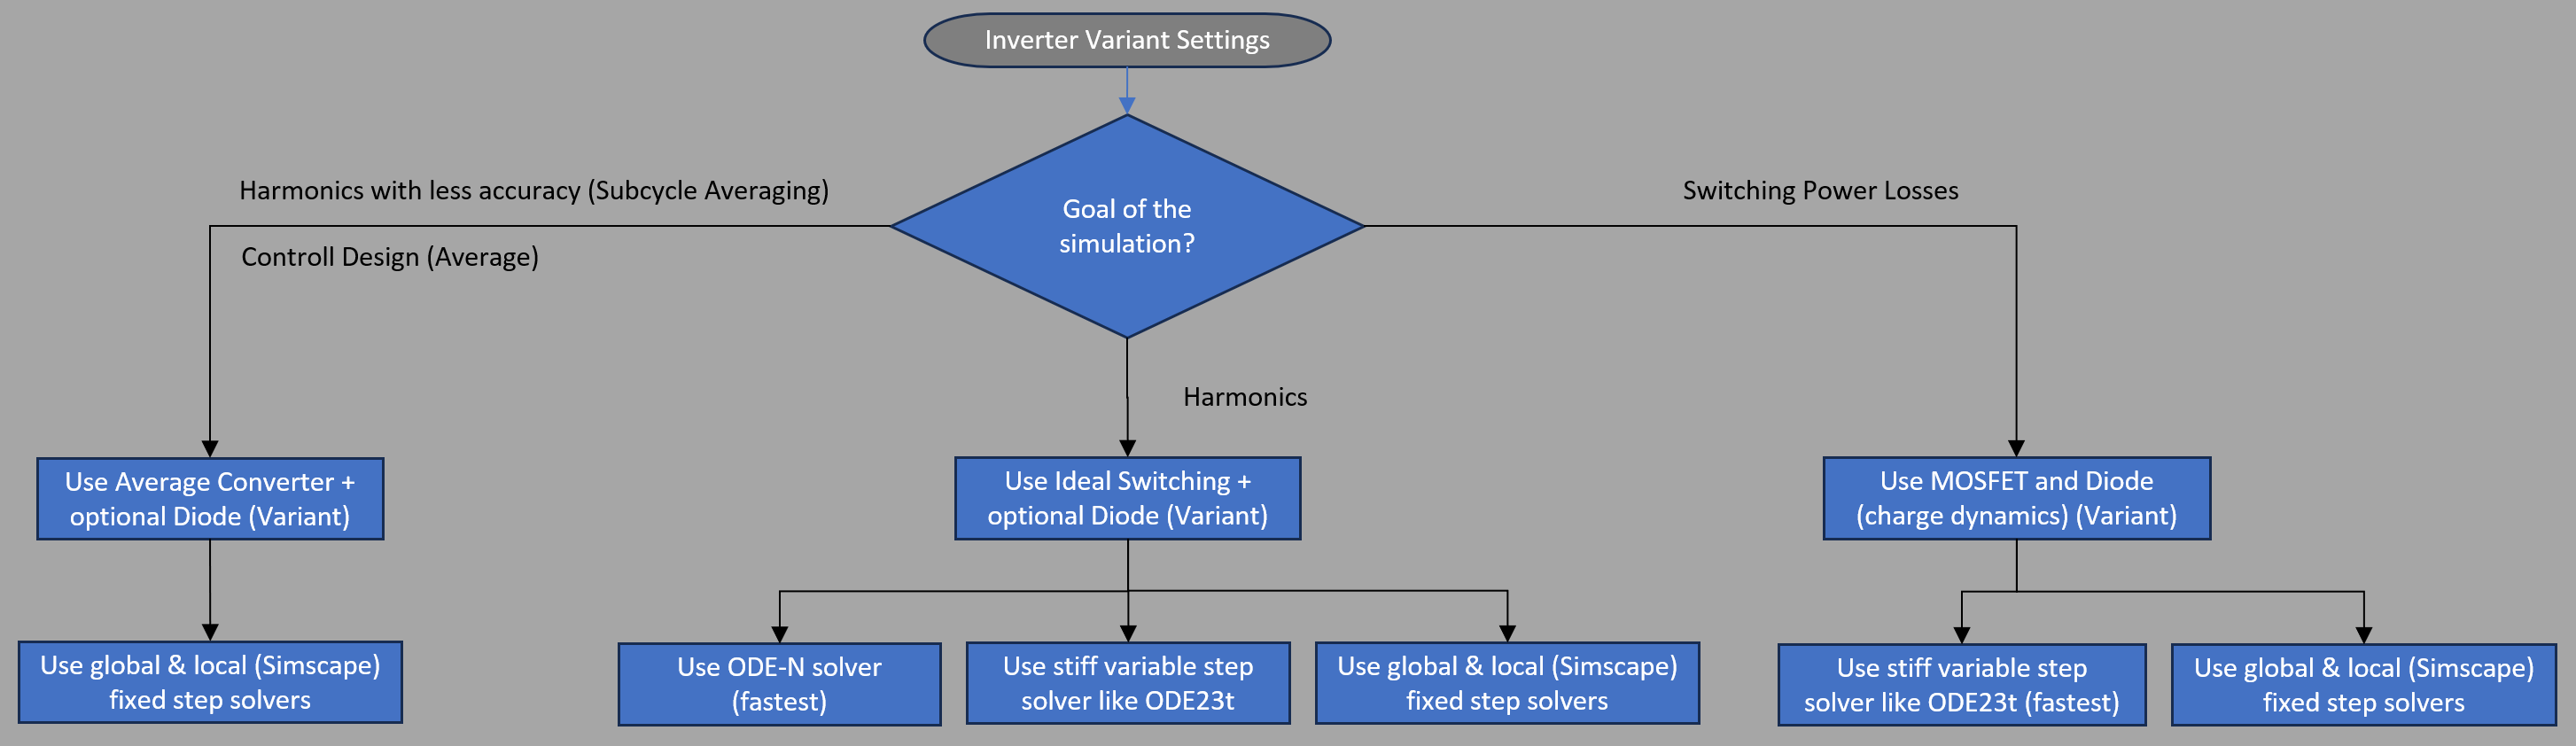

Open the model

if ~bdIsLoaded('comparePWM_modified')
    mdl = 'comparePWM.slx';
    open_system(mdl);

Save under a different file name to prevent reference model to be overwritten

    save_system(mdl,'comparePWM_modified.slx');
end
mdl = gcs;

Simulink.sdi.clear;

## Show Sample Time Colors

Sample Time Colors shows the samlpe time of each individual block of the model. This is a good feedback to make sure all is set correctly.

set_param(mdl,'SampleTimeColors','on');
Simulink.BlockDiagram.getChecksum(mdl);

# `Press Ctrl+J`

All blocks from the left (3-phase sine generator, PWM Timing and Waveform Generator, PWM Accuracy) till the PWM Gates Generator are called with a discrete sample time Tsw = 1/fsw.  They are shown in green.

The PWM Gates Generator uses additionally continuous or a faster discrete sample time. It is indicated as a multirate block.

The inverter and 3-phase RL is using the same sample time as the PWM Gates, here shown in red.

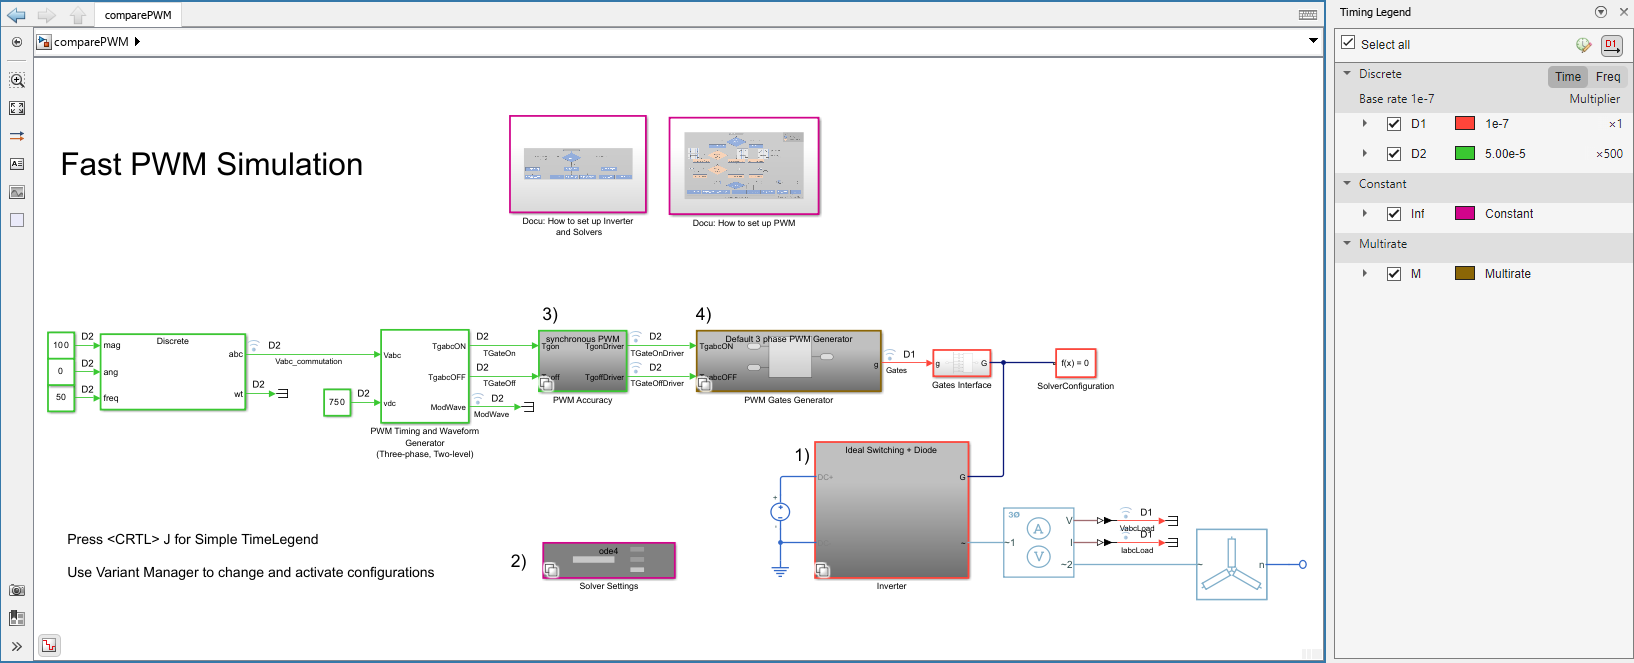

## Print available Variant Configurations

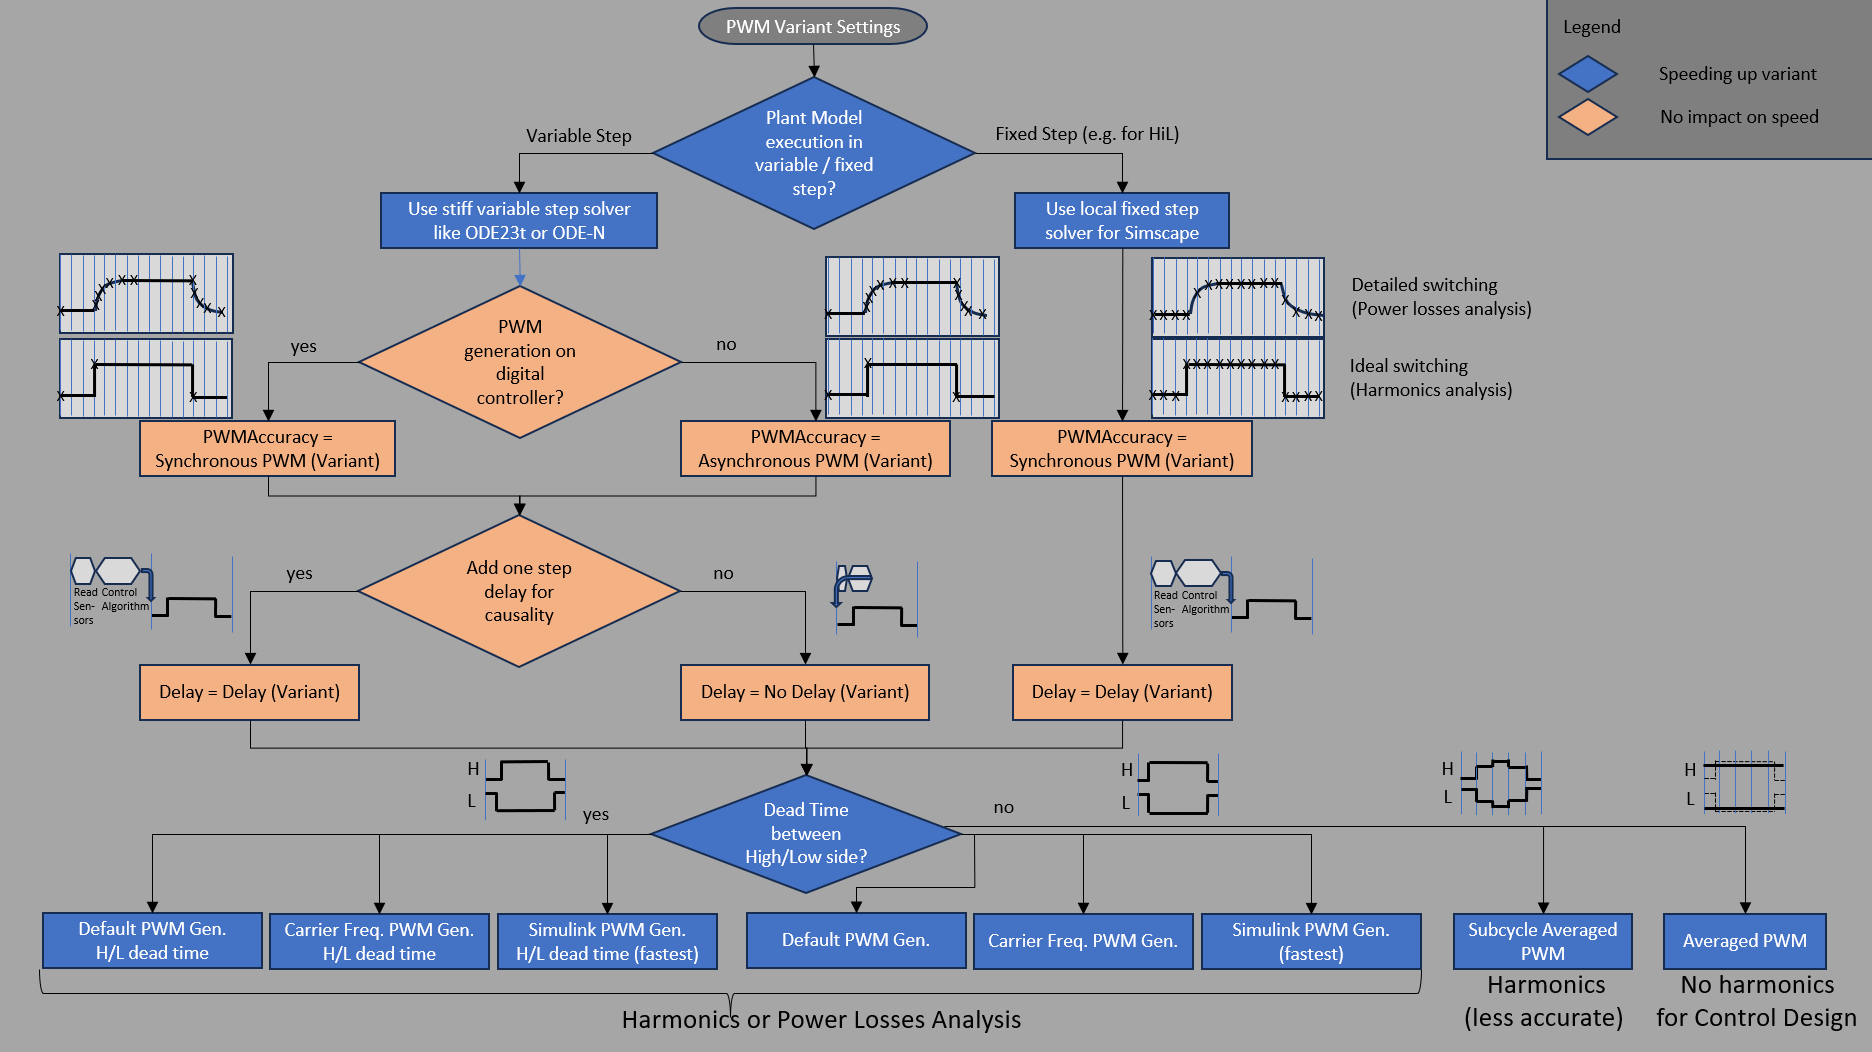

load FastPWMConfigurations
for i=1:length(FastPWM.Configurations)
    disp(FastPWM.Configurations(i).Name);
end

MOSFET_ode23t_Def3PhasePWMGen
MOSFET_ode23t_Def3PhasePWMGenHighLowDeadTime
MOSFET_ode23t_FastSimulinkPWM
MOSFET_ode23t_FastSimulinkPWMHighLowDeadTime
Ideal_ode23t_CarrierFreqPWMGen
Ideal_ode4_CarrierFreqPWMGen
Ideal_ode23t_CarrierFreqPWMGenHighLowDeadTime
Ideal_ode4_CarrierFreqPWMGenHighLowDeadTime
Ideal_ode23t_Def3PhasePWMGen
Ideal_odeN_Def3PhasePWMGen
Ideal_ode4_Def3PhasePWMGen
Ideal_ode23t_Def3PhasePWMGenHighLowDeadTime
Ideal_odeN_Def3PhasePWMGenHighLowDeadTime
Ideal_ode4_Def3PhasePWMGenHighLowDeadTime
Ideal_ode23t_FastSimulinkPWMGen
Ideal_odeN_FastSimulinkPWMGen
Ideal_ode4_FastSimulinkPWMGen
Ideal_ode23t_FastSimulinkPWMGenHighLowDeadTime
Ideal_odeN_FastSimulinkPWMGenHighLowDeadTime
Ideal_ode4_FastSimulinkPWMGenHighLowDeadTime
SubcycleAveraging
Averaging


## Apply predefined Variant Configuration

Select one valid variant configuration that defines the fidelity level of the inverter, the solver and the PWM implementation

Interesting demonstration variants are

- Ideal_ode4_CarrierFreqPWMGen

- Ideal_ode23t_CarrierFreqPWMGen

- Ideal_ode23t_FastSimulinkPWMGen

- SubcycleAveraging

Conf = "Ideal_ode4_CarrierFreqPWMGen"

Conf = "Ideal_ode4_CarrierFreqPWMGen"

Simulink.VariantManager.applyConfiguration(mdl,Configuration=Conf);

## Optionally overwrite PWM configurations that do not influence execution speed

There are three settings that have to be chosen for the PWM

- Does the PWM switching happen only at specific time intervalls (like on digital PWM generators) or can it happen any time?

PWMAccuracy = "sync";

- Is a one PWM cycle time delay needed for causality reasons ? This will be the case on real HW controllers because PWM output cannot start at same time when sensor data is read.

Delay = "Delay";

- Define the dead time that has to be considered between the switching of High and Low side gate signals to prevent a short circuit within the semiconductor bridge

DeadTime = 2e-7; % must be minimum 2xTs 

- Selection of the PWM algorithm

## Measure the execution time during Simulation and plot results

### Stop Fcn Callback

To get the exact information about the execution time a Stop Fcn Callback is used to print it using "out.SimulationMetadata.TimingInfo".

### Close SDI for faster simulation

Simulink.sdi.close;

### Run the Model

clear out;
open_system([mdl,'/Solver Settings']); % This activates the reconfiguration of the solvers
out = sim(mdl);
out.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2024-05-02 14:46:15'
           WallClockTimestampStop: '2024-05-02 14:46:18'
    InitializationElapsedWallTime: 2.4739
         ExecutionElapsedWallTime: 0.1329
       TerminationElapsedWallTime: 0.0477
             TotalElapsedWallTime: 2.6545
                     ProfilerData: 'Profiler is not enabled'


### Compare simulation results with Simulation Data Inspector

Simulink.sdi.view;
Simulink.sdi.setSubPlotLayout(4,2);

lastRun = Simulink.sdi.Run.getLatest;
NameChar = [num2str(out.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime),'sec|',Conf];

lastRun.Name = NameChar;
Vabc_commutation = getSignalsByName(lastRun,'Vabc_commutation');
plotOnSubPlot(Vabc_commutation.Children(1),1,1,true);
plotOnSubPlot(Vabc_commutation.Children(2),1,1,true);
plotOnSubPlot(Vabc_commutation.Children(3),1,1,true);

ModWave = getSignalsByName(lastRun,'ModWave');
plotOnSubPlot(ModWave.Children(1),2,1,true);
plotOnSubPlot(ModWave.Children(2),2,1,true);
plotOnSubPlot(ModWave.Children(3),2,1,true);

TGateOnDriver = getSignalsByName(lastRun,'TGateOnDriver');
plotOnSubPlot(TGateOnDriver.Children(1),3,1,true);
plotOnSubPlot(TGateOnDriver.Children(2),3,1,true);
plotOnSubPlot(TGateOnDriver.Children(3),3,1,true);

TGateOffDriver = getSignalsByName(lastRun,'TGateOffDriver');
plotOnSubPlot(TGateOffDriver.Children(1),4,1,true);
plotOnSubPlot(TGateOffDriver.Children(2),4,1,true);
plotOnSubPlot(TGateOffDriver.Children(3),4,1,true);

Gates = getSignalsByName(lastRun,'Gates'); % only Phase A
expand(Gates);                             % Expand signals to plot 
plotOnSubPlot(Gates.Children(1),1,2,true);
plotOnSubPlot(Gates.Children(2),1,2,true);

VabcLoad = getSignalsByName(lastRun,'VabcLoad');
VabcLoad.Children(1).InterpMethod = 'zoh';    % use ZOH interpolation for correct plot
plotOnSubPlot(VabcLoad.Children(1),2,2,true); % only Phase A

IabcLoad = getSignalsByName(lastRun,'IabcLoad');
plotOnSubPlot(IabcLoad.Children(1),3,2,true);
plotOnSubPlot(IabcLoad.Children(2),3,2,true);
plotOnSubPlot(IabcLoad.Children(3),3,2,true);

## Results

#### Setting

Sample Time Ts = 1e-7 sec (not used for Fast Simulink PWM)

Switching Frequency = 20000 Hz

discrete PWM

One step delay

#### Harmonics Analysis with Ideal Switching + Diode

                                Carrier Freq PWM         Default 3 Phase PWM    Fast Simulink PWM

odeN                           -                                      8.47sec                            0.75sec

ode23t                         3.62sec                          5.83sec                            0.86sec

ode4 + local solver      20.8 sec                         14.4sec                            16.1sec

#### Power Losses Analysis with MOSFET + Diode (charge dynamics)

                                Carrier Freq PWM         Default 3 Phase PWM    Fast Simukink PWM

odeN                            not suitable                       not suitable                    not suitable                (missing resolution)

ode23t                         needs other solver tol        18.9sec                         6.42sec

ode4 + local solver      not tested                          not tested                       not tested                  (needs much smaller sample time)

#### Harmonics Analysis with Subcycle Averaging

ode4 + local solver        0.24sec

#### Average Model

ode4 + local solver        0.17sec